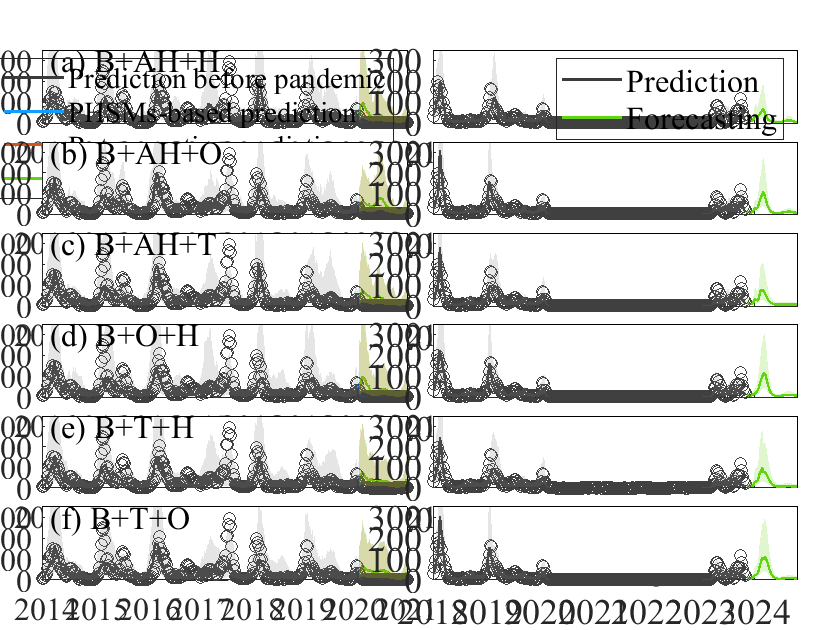

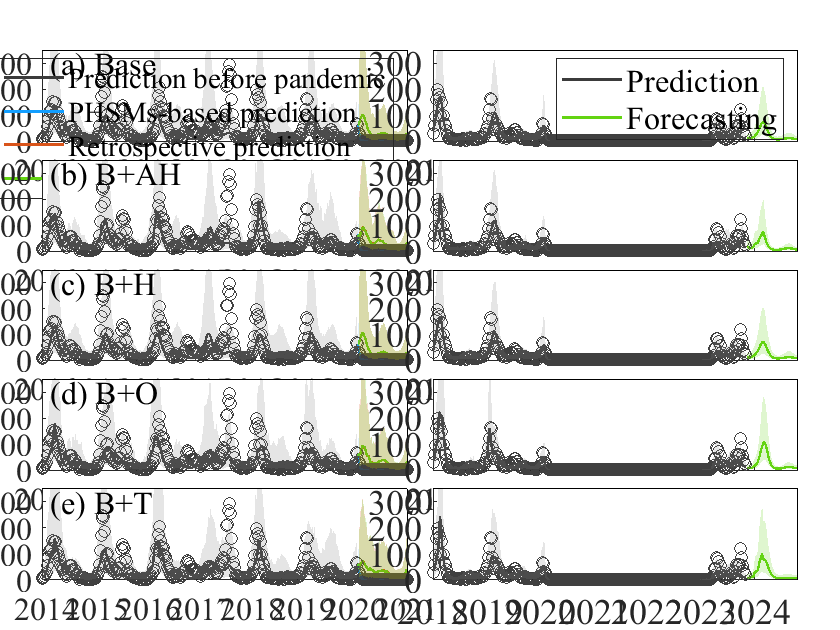

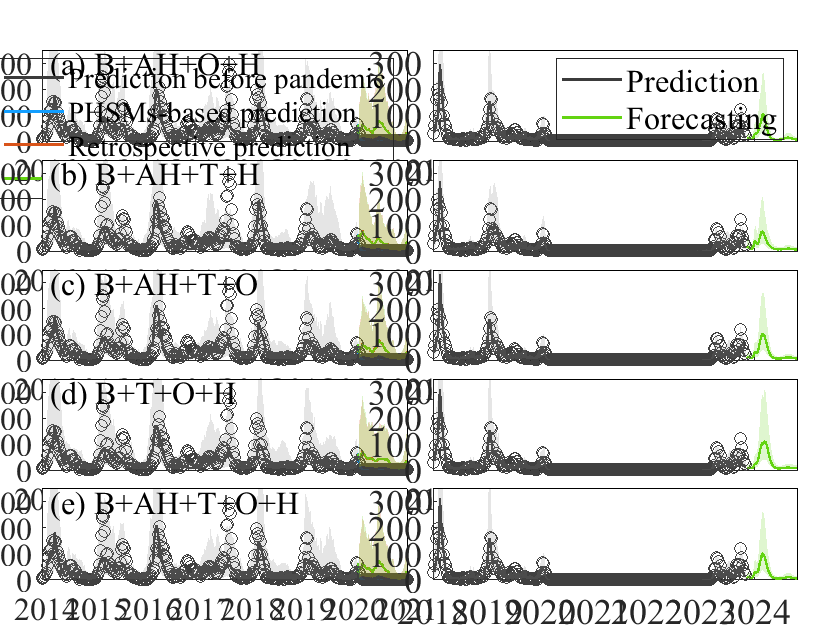

clear;close all
Model_scripts = {'_1Base','_2Base+AH','_2Base+H','_2Base+O','_2Base+T','_3Base+AH+H','_3Base+AH+O','_3Base+AH+T','_3Base+O+H','_3Base+T+H',...
    '_3Base+T+O','_4Base+AH+O+H','_4Base+AH+T+H','_4Base+AH+T+O','_4Base+T+O+H','_5Base+AH+T+O+H'};
Name = {'(a) Base','(b) B+AH','(c) B+H','(d) B+O','(e) B+T','(a) B+AH+H','(b) B+AH+O','(c) B+AH+T','(d) B+O+H','(e) B+T+H',...
    '(f) B+T+O','(a) B+AH+O+H','(b) B+AH+T+H','(c) B+AH+T+O','(d) B+T+O+H','(e) B+AH+T+O+H'};

address = Model_scripts;
lims = [0.025,0.5,0.975];
model_number={[1:5],[6:11],[12:16]};

 for number1 = 1:3
     figure();
    ha=tight_subplot(length(model_number{number1}),2,0.03,0.08,0.05);%hold on;
    figs = 0;
    for number = 1:numel(model_number{number1})  
    % cd ('F:\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
    % cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
    cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
    END1 = 373;figs=figs+1;
     cd (address{model_number{number1}(number)});
     load(sprintf('ABase_%d.mat',2014),'PIdata','PIdataCF','A');
     load(sprintf('PICF_Fore_ave_%d.mat',2014));PIdata(:,1)=A(204);PIdataCF(:,1)=A(204);PIdataCF_Fore(:,1)=A(204);
     PIdata(:,322)=A(525);PIdataCF(:,322)=A(525);PIdataCF_Fore(:,322)=A(525);
     if strcmpi(address{model_number{number1}(number)},{'_1Base'}) || strcmpi(address{model_number{number1}(number)},{'_2Base+H'}) 
         PIdataCF_Fore = PIdataCF;
     end
     Rlim_Long = plims(PIdata,lims); Rlim_Long=Rlim_Long(:,1:END1);
     Rlim_LongCF = plims(PIdataCF,lims);Rlim_LongCF=Rlim_LongCF(:,1:END1);
     Rlim_LongCF_Fore = plims(PIdataCF_Fore,lims);Rlim_LongCF_Fore=Rlim_LongCF_Fore(:,1:END1); 
    
% subplot(length(model_number{number1}),2,figs);hold on;
axes(ha(figs));hold on;
plot(204:203+END1-51,Rlim_Long(2,1:end-51),"Color",[0.23,0.23,0.23],"LineWidth",1.2)
plot(203+322:203+length(Rlim_LongCF),Rlim_Long(2,end-51:end),"Color",[0.07,0.62,1.00],"LineWidth",1.2)
plot(203+322:203+length(Rlim_LongCF),Rlim_LongCF(2,end-51:end),'Color',[0.85,0.33,0.10],'LineWidth',1.2)
plot(203+322:203+length(Rlim_LongCF),Rlim_LongCF_Fore(2,end-51:end),'Color',[0.39,0.83,0.07],'LineWidth',1.2)
plot(204:203+END1,A(204:203+END1),'O',"Color",[0.25,0.25,0.25])
fillyy(204:203+END1-51,Rlim_Long(1,1:end-51),Rlim_Long(3,1:end-51),[0.5,0.5,0.5],0.2); %obs 95CI

fillyy(203+322:203+length(Rlim_LongCF),Rlim_Long(1,end-51:end),Rlim_Long(3,end-51:end),[0.07,0.62,1.00],0.12); %obs 95CI
fillyy(204+322:203+END1,Rlim_LongCF(1,323:END1),Rlim_LongCF(3,323:END1),[0.85,0.33,0.10],0.2); %obs 95CI
fillyy(204+322:203+END1,Rlim_LongCF_Fore(1,323:END1),Rlim_LongCF_Fore(3,323:END1),[0.39,0.83,0.07],0.2); %obs 95CI
xlim([204 575]);ylim([0 350]);set(gca,'xtick',[208:52.25:575]);
set(gca,'xticklabel',{'2014','2015','2016','2017','2018','2019','2020','2021'});
set(gca,'ytick',[0:100:350]);
set(gca,'yticklabel',{'0','100','200','300'});
set(get(gca,'YLabel'),'FontSize',16);set(get(gca,'XLabel'),'FontSize',24);
text(212,300,Name{model_number{number1}(number)},"FontSize",16,'FontName','Times New Roman')
set(gca,'FontName','Times New Roman','FontSize',16);
if figs == 5
    ylabel(sprintf('Influenza activity\n (ILI+ proxy/10000)'),'FontSize',24)
end
if figs == 9 || figs == 11
    xlabel(sprintf('Time'),'FontSize',24)
end
box_off
if figs == 1
legend('Prediction before pandemic','PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none')
end

     END2 = 348+14;figs=figs+1;
     cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
     cd (address{model_number{number1}(number)});

     load(sprintf('ABase_%d.mat',2018),'PIdata','PIdataCF','A');
     PIdata(:,1)=A(381);PIdataCF(:,1)=A(381);PIdataCF_Fore(:,1)=A(381);
     Rlim_Long = plims(PIdata,lims); Rlim_Long=Rlim_Long(:,1:END2);
     % Rlim_LongCF = plims(PIdataCF,lims);Rlim_LongCF=Rlim_LongCF(:,1:END2);
     % Rlim_LongCF_Fore = plims(PIdataCF_Fore,lims);Rlim_LongCF_Fore=Rlim_LongCF_Fore(:,1:END2); 
% subplot(length(model_number{number1}),2,figs);hold on;
axes(ha(figs));hold on;
plot(381+31:381+327+14,Rlim_Long(2,1:end-51),"Color",[0.23,0.23,0.23],"LineWidth",1.2)
plot(709+14:709+50+14,Rlim_Long(2,end-50:end),"Color",[0.39,0.83,0.07],"LineWidth",1.2)
plot(381+31:329+31+END2,A(381+31:329+31+END2),'O',"Color",[0.25,0.25,0.25])
fillyy(381+31:381+327+14,Rlim_Long(1,1:end-51),Rlim_Long(3,1:end-51),[0.5,0.5,0.5],0.2); %obs 95CI
fillyy(709+14:709+50+14,Rlim_Long(1,end-50:end),Rlim_Long(3,end-50:end),[0.39,0.83,0.07],0.2); %obs 95CI
xlim([365+52.25 773]);ylim([0 350]);set(gca,'xtick',[365+52.25:52.25:760]);
set(gca,'xticklabel',{'2018','2019','2020','2021','2022','2023','2024'});
set(gca,'ytick',[0:100:350]);set(gca,'yticklabel',{'0','100','200','300'});
set(get(gca,'YLabel'),'FontSize',15);set(get(gca,'XLabel'),'FontSize',20);
set(gca,'FontName','Times New Roman','FontSize',18);
if figs == 10 || figs == 12
    xlabel(sprintf('Time'),'FontSize',24)
end
box_off
if figs == 2
    legend('Prediction','Forecasting','color','none')
end

    end
 end
exportgraphics(gcf,sprintf('FigureS 13 Fitting_forecasting_sensitivity_long_%d.pdf',number1),'ContentType','vector')



% ha=tight_subplot(5,2,0.05,0.1,0.1)

% ha = tight_subplot(5,2,[.01 .03],[.1 .01],[.01 .01])




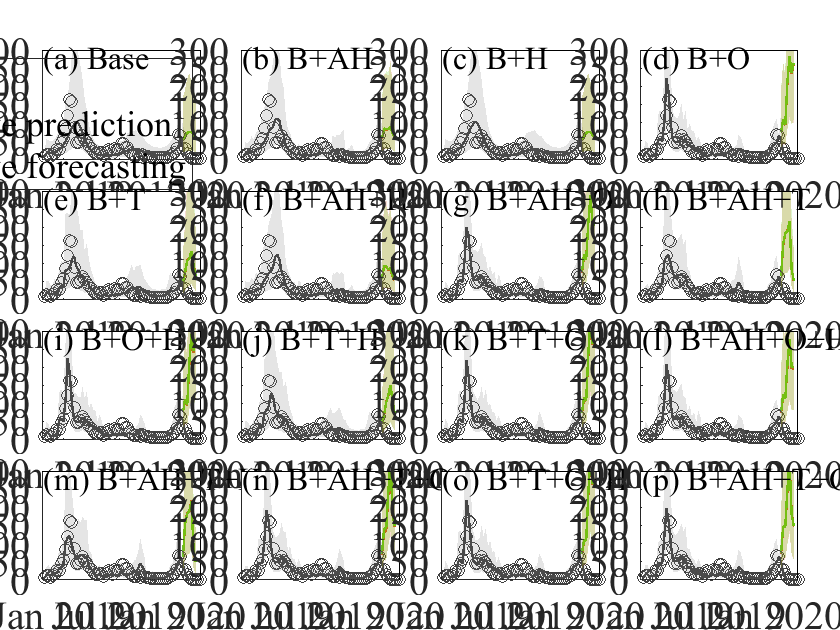


clear;close all
Model_scripts = {'_1Base','_2Base+AH','_2Base+H','_2Base+O','_2Base+T','_3Base+AH+H','_3Base+AH+O','_3Base+AH+T','_3Base+O+H','_3Base+T+H',...
    '_3Base+T+O','_4Base+AH+O+H','_4Base+AH+T+H','_4Base+AH+T+O','_4Base+T+O+H','_5Base+AH+T+O+H'};
Name = {'(a) Base','(b) B+AH','(c) B+H','(d) B+O','(e) B+T','(f) B+AH+H','(g) B+AH+O','(h) B+AH+T','(i) B+O+H','(j) B+T+H',...
    '(k) B+T+O','(l) B+AH+O+H','(m) B+AH+T+H','(n) B+AH+T+O','(o) B+T+O+H','(p) B+AH+T+O+H'};

address = Model_scripts;
lims = [0.025,0.5,0.975];
model_number={[1:5],[6:11],[12:16]};
ha=tight_subplot(4,4,0.05,0.08,0.05);%hold on;  
figs = 0;
 for number1 = 1:3
    for number = 1:numel(model_number{number1})  
    % cd ('F:\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
    % cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
    cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
    ENDSHORT = 72;figs=figs+1;
     cd (address{model_number{number1}(number)});
     load(sprintf('ABase_%d.mat',2019),'PIdata','PIdataCF','A');
     load(sprintf('PICF_Fore_ave_%d.mat',2019));PIdata(:,1)=A(461);PIdataCF(:,1)=A(461);PIdataCF_Fore(:,1)=A(461);
     PIdata(:,65)=A(525);PIdataCF(:,65)=A(525);PIdataCF_Fore(:,65)=A(525);

     Rlim_Short = plims(PIdata,lims); Rlim_Short=Rlim_Short(:,1:end-44-147);
     Rlim_ShortCF = plims(PIdataCF,lims);Rlim_ShortCF=Rlim_ShortCF(:,1:ENDSHORT);
     Rlim_ShortCF_Fore = plims(PIdataCF_Fore,lims);Rlim_ShortCF_Fore=Rlim_ShortCF_Fore(:,1:ENDSHORT); 
     if strcmpi(address{model_number{number1}(number)},{'_1Base'}) | strcmpi(address{model_number{number1}(number)},{'_2Base+H'}) 
         Rlim_ShortCF_Fore = Rlim_ShortCF;
     end
    
% subplot(length(model_number{number1}),2,figs);hold on;
axes(ha(figs));hold on;
plot(461:473+ENDSHORT-7,Rlim_Short(2,1:13+ENDSHORT-7),"Color",[0.23,0.23,0.23],"LineWidth",1.2)
% plot(461:460+116,Rlim_Short(2,1:end-7),"Color",[0.23,0.23,0.23],"LineWidth",1.2)
plot(460+ENDSHORT-6:460+ENDSHORT,Rlim_ShortCF(2,ENDSHORT-6:ENDSHORT),'Color',[0.85,0.33,0.10],'LineWidth',1.2)
plot(460+ENDSHORT-6:460+ENDSHORT,Rlim_ShortCF_Fore(2,end-6:end),'Color',[0.39,0.83,0.07],'LineWidth',1.2)
plot(709+14:715+14,Rlim_Short(2,end-6:end),"Color",[0.07,0.62,1.00],"LineWidth",1.2)
plot(461:722,A(461:722),'O',"Color",[0.25,0.25,0.25])

% plot(525:526,Rlim_ShortCF(2,end-7:end-6),':',"Color",[0.85,0.33,0.10],"LineWidth",1.2)
% plot(525:526,Rlim_ShortCF_Fore(2,end-7:end-6),':',"Color",[0.39,0.83,0.07],"LineWidth",1.2)
plot(708+14:709+14,Rlim_Short(2,end-7:end-6),':',"Color",[0.07,0.62,1.00],"LineWidth",1.2)


fillyy(461:473+ENDSHORT-7,Rlim_Short(1,1:13+ENDSHORT-7),Rlim_Short(3,1:13+ENDSHORT-7),[0.5,0.5,0.5],0.2); %obs 95CI
fillyy(461+ENDSHORT-7:460+ENDSHORT,Rlim_ShortCF(1,ENDSHORT-6:ENDSHORT),Rlim_ShortCF(3,ENDSHORT-6:ENDSHORT),[0.85,0.33,0.10],0.2); %obs 95CI
fillyy(461+ENDSHORT-7:460+ENDSHORT,Rlim_ShortCF_Fore(1,ENDSHORT-6:ENDSHORT),Rlim_ShortCF_Fore(3,ENDSHORT-6:ENDSHORT),[0.39,0.83,0.07],0.2); %obs 95CI
fillyy(709+14:715+14,Rlim_Short(1,end-6:end),Rlim_ShortCF_Fore(3,end-6:end),[0.07,0.62,1.00],0.2); %obs 95CI

xlim([460 534]);ylim([0 300]);set(gca,'xtick',[470:26.1250:716+14]);
set(gca,'xticklabel',{'Jan 2019','Jul 2019','Jan 2020','2021','2022','2023','2024'});
set(gca,'ytick',[0:50:350]);
set(gca,'yticklabel',{'0','50','100','150','200','250','300'});
set(get(gca,'YLabel'),'FontSize',14);set(get(gca,'XLabel'),'FontSize',14);
text(460.5,280,Name{model_number{number1}(number)},"FontSize",16,'FontName','Times New Roman')
set(gca,'FontName','Times New Roman','FontSize',20);
if  figs == 9 
    ylabel(sprintf('Influenza activity\n (ILI+ proxy/10000)'),'FontSize',24)
end
if figs == 13 || figs == 14|| figs == 15|| figs == 16
    xlabel(sprintf('Time'),'FontSize',24)
end
box_off
if figs == 1
legend('Prediction','Retrospective prediction','Retrospective forecasting','color','none')
end


    end
 end

%exportgraphics(gcf,sprintf('FigureS 11 Fitting_Rforecasting_sensitivity_short_%d.pdf',number1),'ContentType','vector')



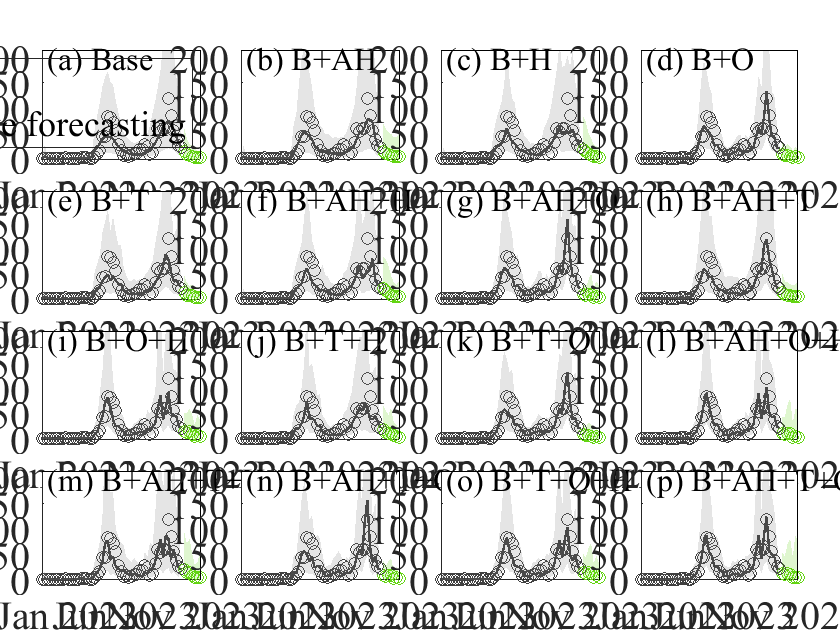



clear;close all
Model_scripts = {'_1Base','_2Base+AH','_2Base+H','_2Base+O','_2Base+T','_3Base+AH+H','_3Base+AH+O','_3Base+AH+T','_3Base+O+H','_3Base+T+H',...
    '_3Base+T+O','_4Base+AH+O+H','_4Base+AH+T+H','_4Base+AH+T+O','_4Base+T+O+H','_5Base+AH+T+O+H'};
Name = {'(a) Base','(b) B+AH','(c) B+H','(d) B+O','(e) B+T','(f) B+AH+H','(g) B+AH+O','(h) B+AH+T','(i) B+O+H','(j) B+T+H',...
    '(k) B+T+O','(l) B+AH+O+H','(m) B+AH+T+H','(n) B+AH+T+O','(o) B+T+O+H','(p) B+AH+T+O+H'};

address = Model_scripts;
lims = [0.025,0.5,0.975];
model_number={[1:5],[6:11],[12:16]};

ha=tight_subplot(4,4,0.05,0.08,0.05);%hold on;  
figs = 0;
 for number1 = 1:3
    for number = 1:numel(model_number{number1})  
    % cd ('F:\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
    % cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
    cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
    figs=figs+1;
     cd (address{model_number{number1}(number)});
     load(sprintf('ABase_%d.mat',2023),'PIdata','A');
     PIdata(:,1)=A(669);PIdata(:,54)=A(722);

     Rlim_Short = plims(PIdata,lims); Rlim_Short=Rlim_Short(:,1:end-45);
    
% subplot(length(model_number{number1}),2,figs);hold on;
axes(ha(figs));hold on;
plot(669:669+53,Rlim_Short(2,1:end-7),"Color",[0.23,0.23,0.23],"LineWidth",1.2)
plot(723:729,Rlim_Short(2,end-6:end),':o',"Color",[0.39,0.83,0.07],"LineWidth",0.5)
plot(669:722,A(669:722),'o',"Color",[0.25,0.25,0.25])
% plot(708+14:709+14,Rlim_Short(2,end-7:end-6),':',"Color",[0.39,0.83,0.07],"LineWidth",1.2)
fillyy(669:669+53,Rlim_Short(1,1:end-7),Rlim_Short(3,1:end-7),[0.5,0.5,0.5],0.2); %obs 95CI
fillyy(723:729,Rlim_Short(1,end-6:end),Rlim_Short(3,end-6:end),[0.39,0.83,0.07],0.2); %obs 95CI

xlim([669 729]);ylim([0 215]);set(gca,'xtick',[679 700.5 722.5]);
set(gca,'xticklabel',{'Jan 2023','Jun 2023','Nov 2023'});
set(gca,'ytick',[0:50:350]);
set(gca,'yticklabel',{'0','50','100','150','200','250','300'});
set(get(gca,'YLabel'),'FontSize',18);set(get(gca,'XLabel'),'FontSize',18);
text(671,200,Name{model_number{number1}(number)},"FontSize",16,'FontName','Times New Roman')
set(gca,'FontName','Times New Roman','FontSize',20);
if  figs == 9 
    ylabel(sprintf('Influenza activity\n (ILI+ proxy/10000)'),'FontSize',24)
end
if figs == 13 || figs == 14|| figs == 15|| figs == 16
    xlabel(sprintf('Time'),'FontSize',24)
end
box_off
if figs == 1
legend('Prediction','Prospective forecasting','color','none')
end


    end
 end
exportgraphics(gcf,sprintf('FigureS 12 Fitting_Pforecasting_sensitivity_short_%d.pdf',number1),'ContentType','vector')